# RL agent Donor agnostic (no UA6 yes UA4 UA141)

DQN without recurring neural network

Dilution penalty is applied when experiment ends prematurely

format shortG
seed = 0

seed =      0


No U donors no T038 (donor #7)

allmodelfoldincs = readmatrix("allmodelfoldincs.txt")

allmodelfoldincs =             1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1
            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1     

modelinitcons = readmatrix("modelinitcons.txt")

modelinitcons =       400000      420000      440000      460000      480000      500000      520000      540000      560000      580000      600000


rawfoldincs = readmatrix("rawfoldincs.txt")

rawfoldincs =             1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1
        1.078         1.53        1.358        1.548        1.052        1.052         0.94        0.718       1.0855         1.19        1.131       1.5582        1.952       1.1377       1.1583       1.0556        0.962        1.076         0.94         0.94         1.13          0.9         0.83        0.865         1.05         0.94         1.17         1.13         0.94         0.38          0.6       0.7625            1            1            1            1            1
       6.1224       4.

rawinitcons = readmatrix("rawinitcons.txt")

rawinitcons =       500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      360000      360000      500000      500000      100000      100000      100000      100000      100000      100000      100000      100000      100000      100000      100000      100000      100000      100000      500000      500000      500000      500000      500000


truecon = readtable("true con.xlsx");
truecon(:,1)=[];
rawdonornames = truecon.Properties.VariableNames;
rawdonornames = string(rawdonornames);
rawdonornames = strrep(rawdonornames,"_","-")

rawdonornames = 1×37 string array
    "T054-1"    "T046-1"    "T051-1"    "T062-1"    "T031-1"    "T031-2"    "T052-1"    "T038-1"    "T036-1"    "T036-2"    "T036-3"    "T066-1"    "T066-2"    "T066-3"    "UA4-1"    "UA4-2"    "UA4-3"    "UA4-4"    "UA4-5"    "UA4-6"    "UA4-7"    "UA4-8"    "UA4-9"    "UA4-10"    "UA4-11"    "UA4-12"    "UA4-13"    "UA141-1"    "UA141-2"    "UA141-3"    "UA141-4"    "UA141-5"    "UA6-1"    "UA6-2"    "UA6-3"    "UA6-4"    "UA6-5"


% rawdonornames = ["T054","T046","T051","T062","T031","T031","T052","T038","T036","T036","T036","T066","T066","T066","UA4","UA4","UA4","UA4","UA4","UA4","UA4","UA4","UA4","UA4","UA4","UA4","UA4","UA141","UA141","UA141","UA141","UA141","UA6","UA6","UA6","UA6","UA6"]
donorlist = ["T054","T046","T051","T062","T031","T052","T038","T036","T066","UA4","UA141","UA6"]

donorlist = 1×12 string array
    "T054"    "T046"    "T051"    "T062"    "T031"    "T052"    "T038"    "T036"    "T066"    "UA4"    "UA141"    "UA6"


donoridxmap = {1,2,3,4,5:6,7,8,9:11,12:14,15:27,28:32,33:37}

donoridxmap = 1×12 cell array
    {[1]}    {[2]}    {[3]}    {[4]}    {[5 6]}    {[7]}    {[8]}    {[9 10 11]}    {[12 13 14]}    {[15 16 17 18 19 20 21 22 23 24 25 26 27]}    {[28 29 30 31 32]}    {[33 34 35 36 37]}


Run training and validation 

Randomization: 

-6:3 training:validation split for tall the T donors

+ 2 ua4 ua141 donors always included

ua6 never included

numdonors = 8

All validation set printed

initializedatasets(seed,allmodelfoldincs,modelinitcons,rawfoldincs,rawinitcons,rawdonornames,donoridxmap,donorlist);

trainingset = 1×8 string array
    "T046"    "T051"    "T062"    "T031"    "T036"    "T066"    "UA4"    "UA141"


validationset = 1×6 string array
    "T054"    "T052"    "T038"    "UA4"    "UA141"    "UA6"


trialmodelfoldincs =             1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1
            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1   


numdonors = 8;

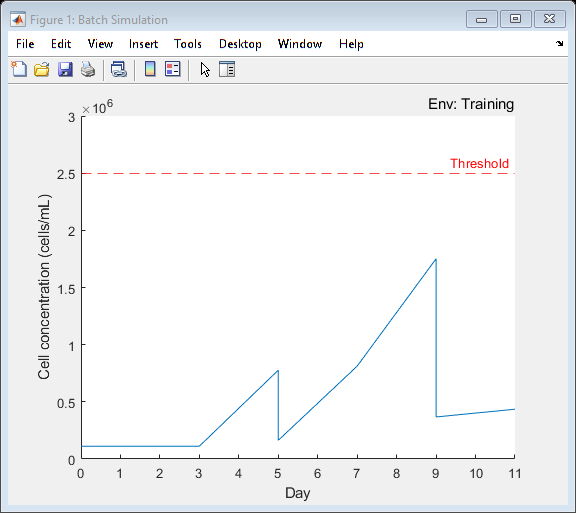

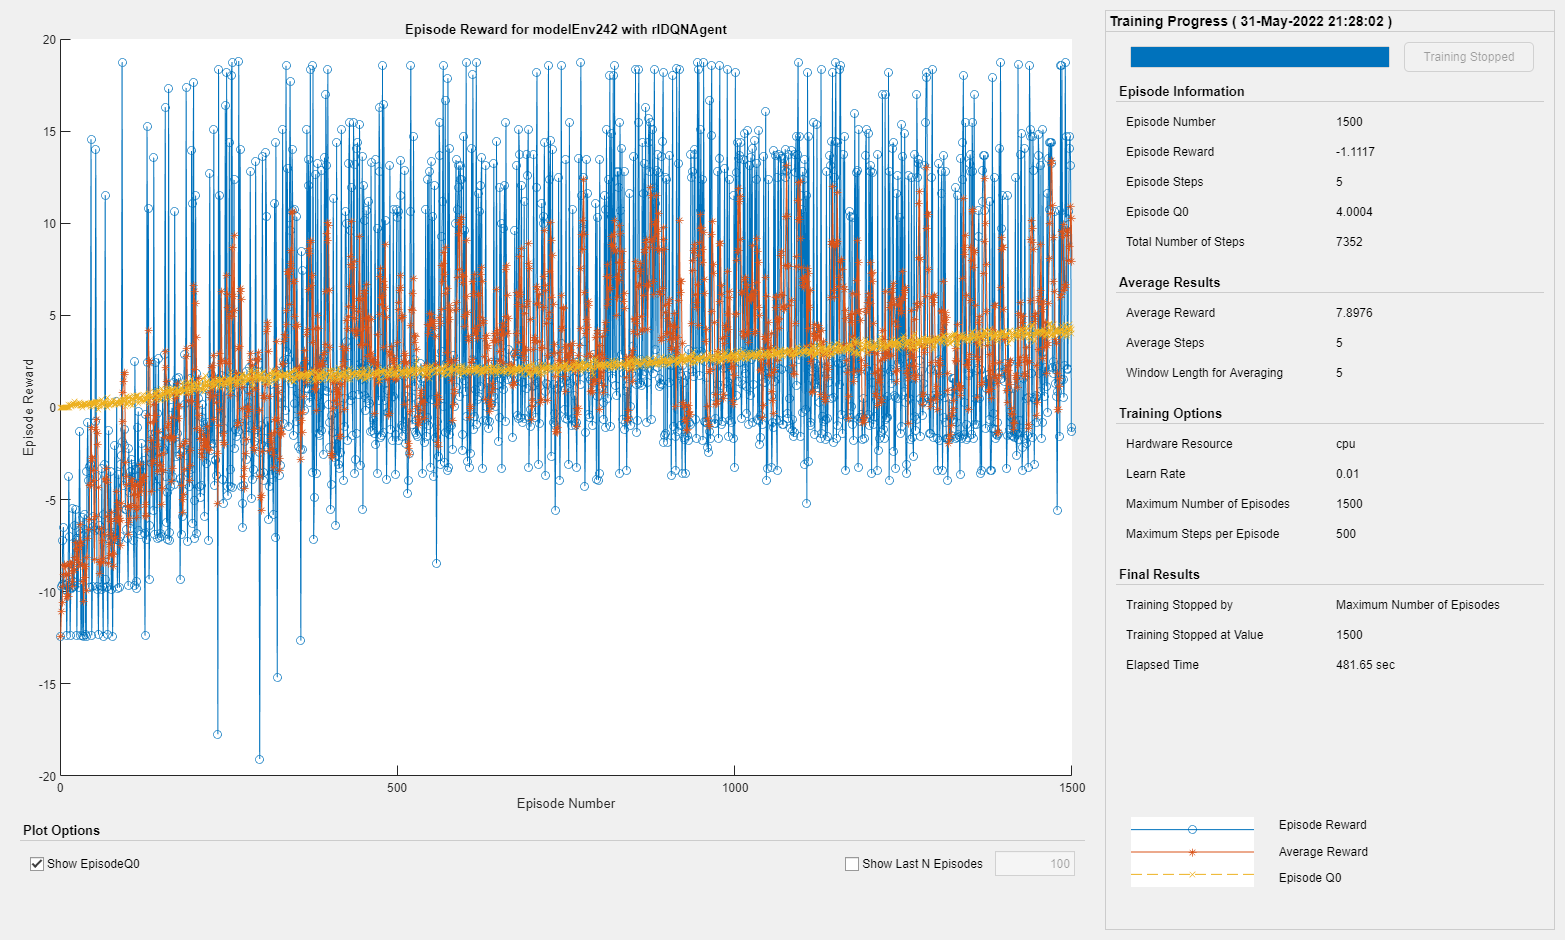

dqnagent = dqninittraining(seed,numdonors);

save("agent_2.4.6_1500ep","dqnagent")
    

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T054-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [4×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


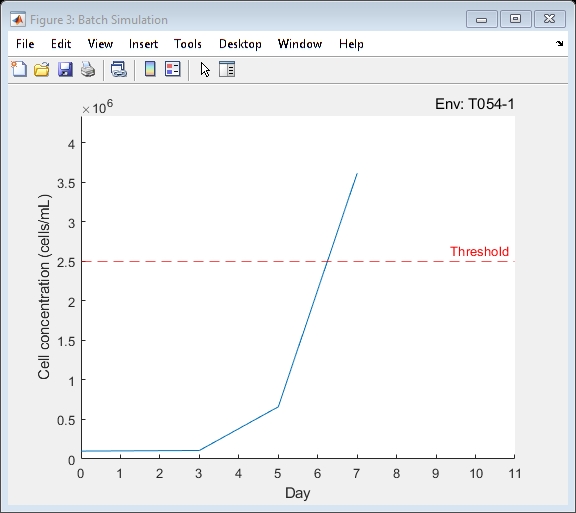

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T046-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [5×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


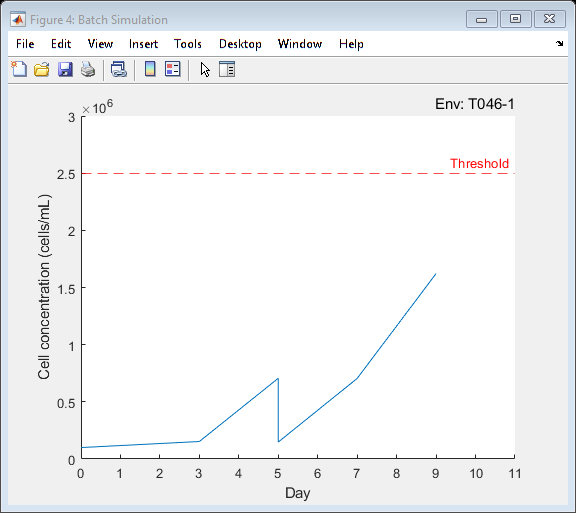

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T051-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


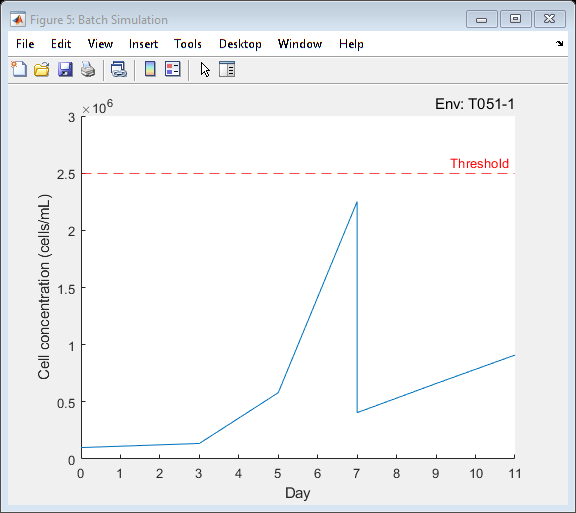

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T062-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


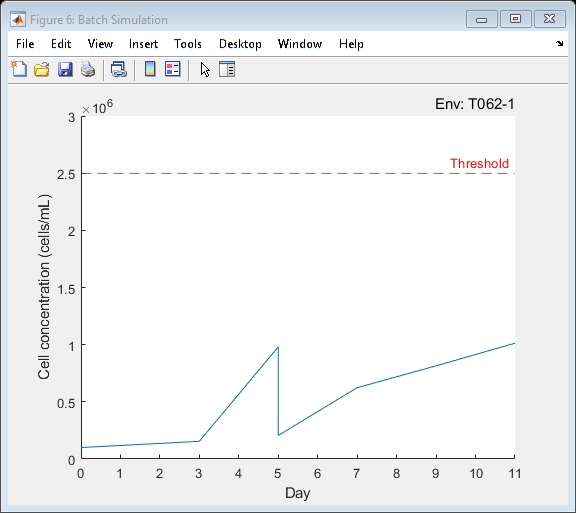

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T031-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [5×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


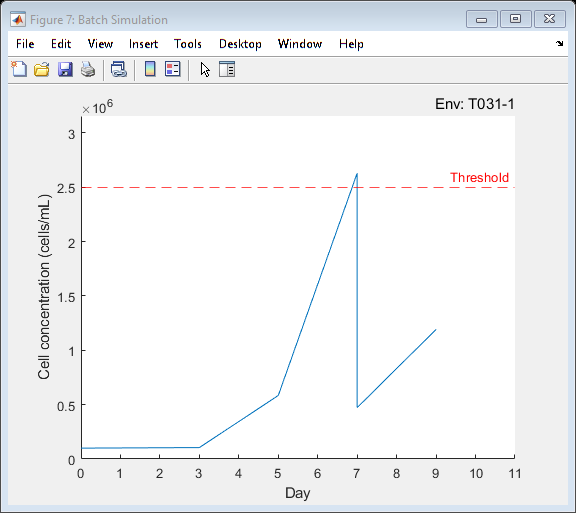

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T031-2"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


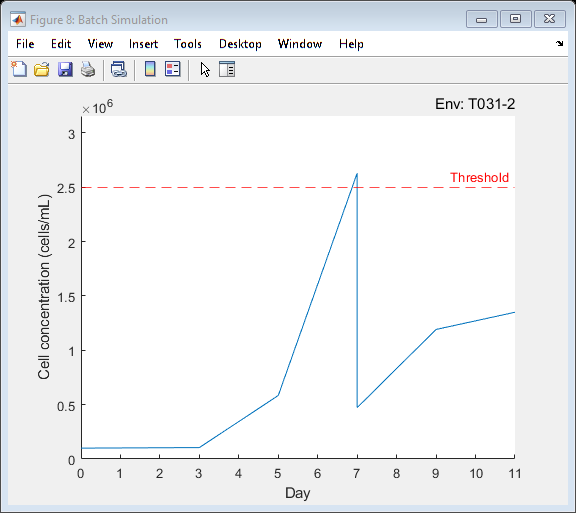

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T052-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


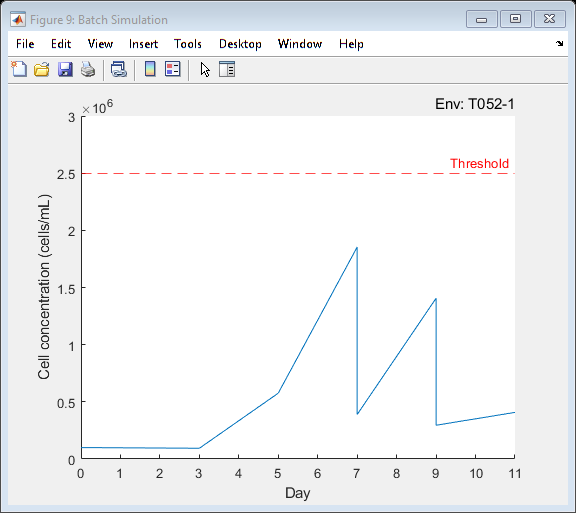

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T038-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


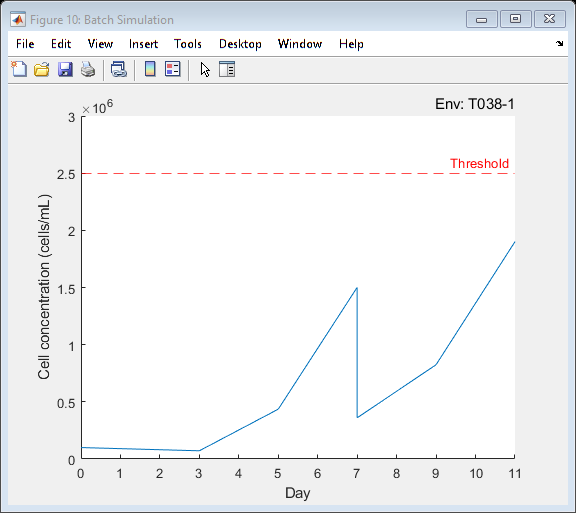

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T036-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


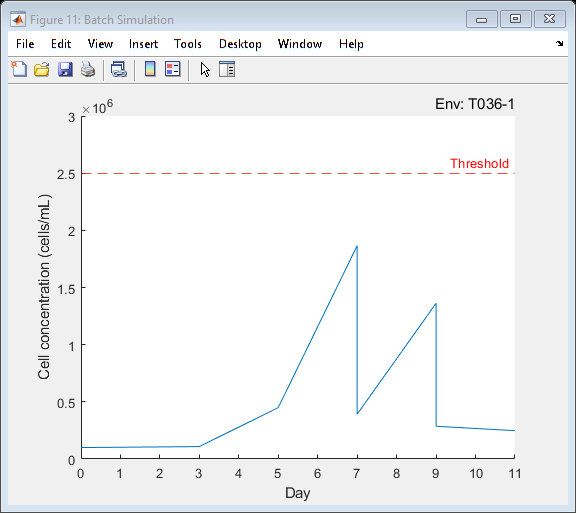

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T036-2"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


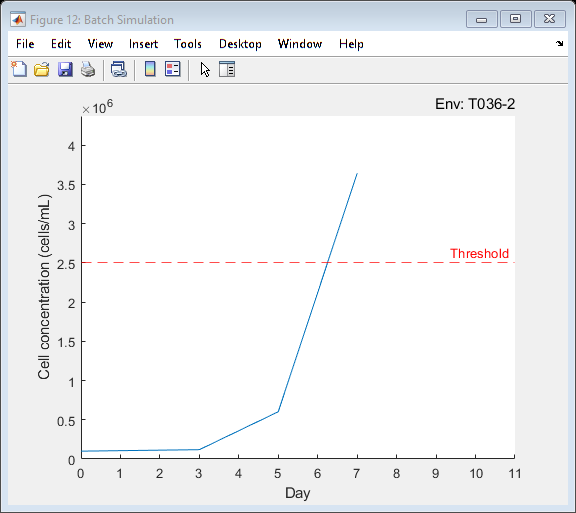

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T036-3"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


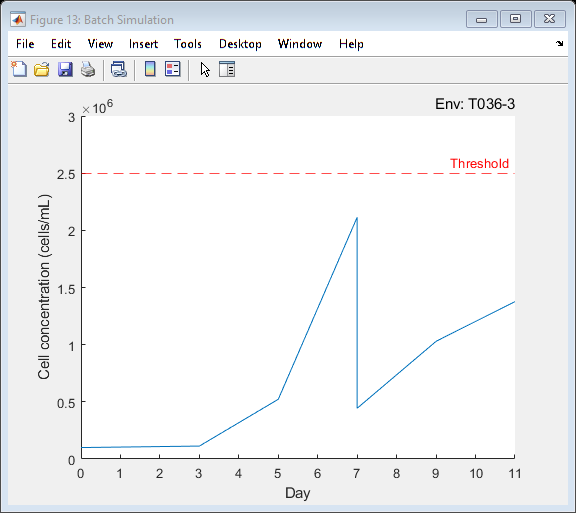

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T066-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


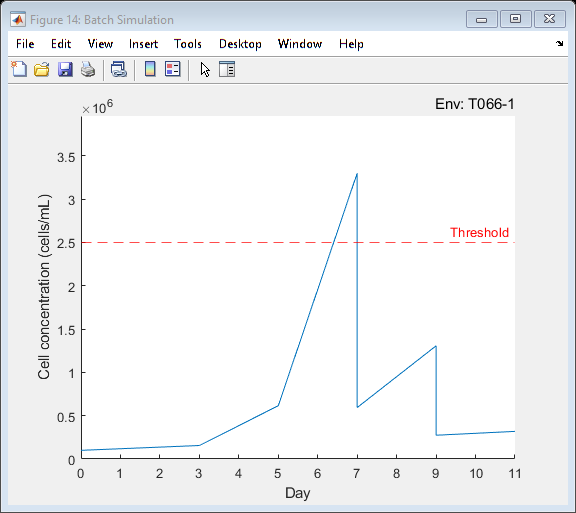

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T066-2"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


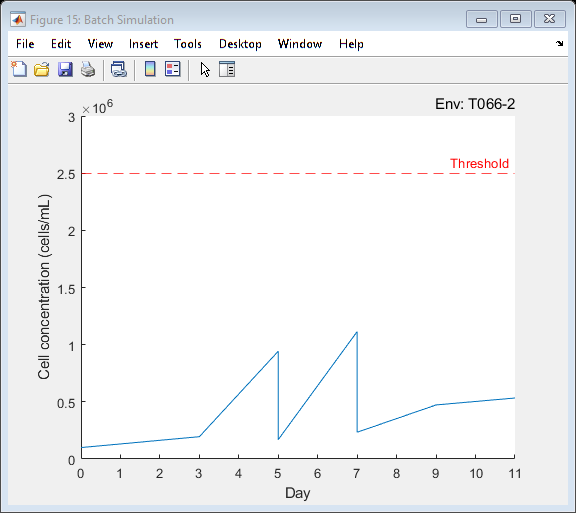

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T066-3"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


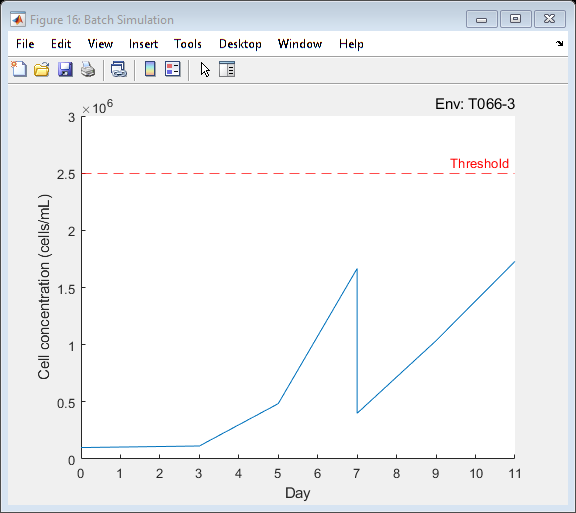

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA4-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [4×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


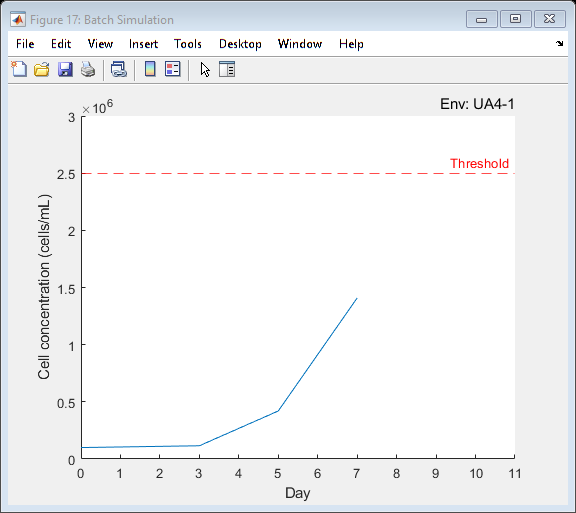

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA4-2"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [4×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


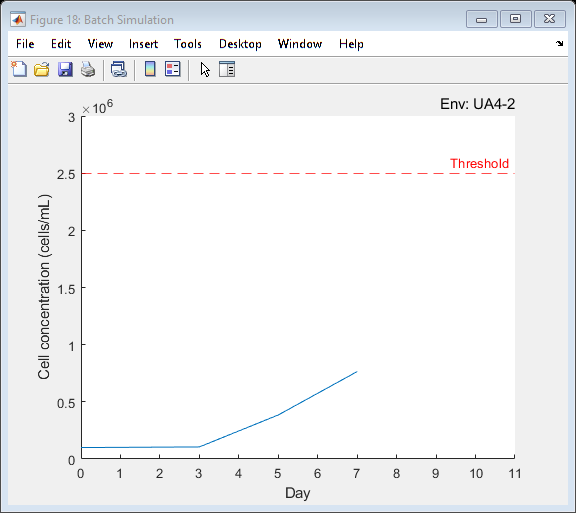

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA4-3"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [4×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


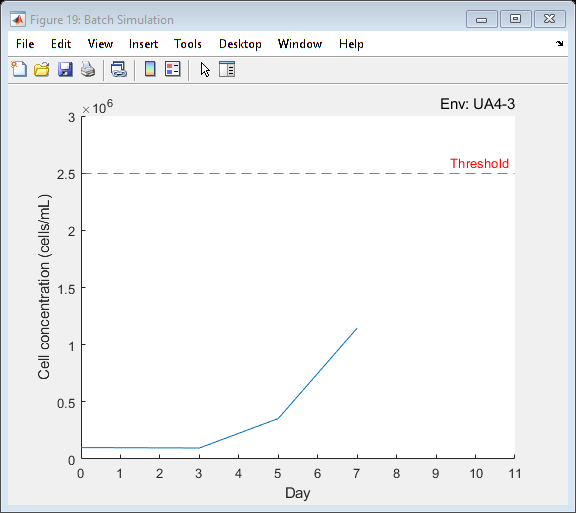

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA4-4"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [4×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


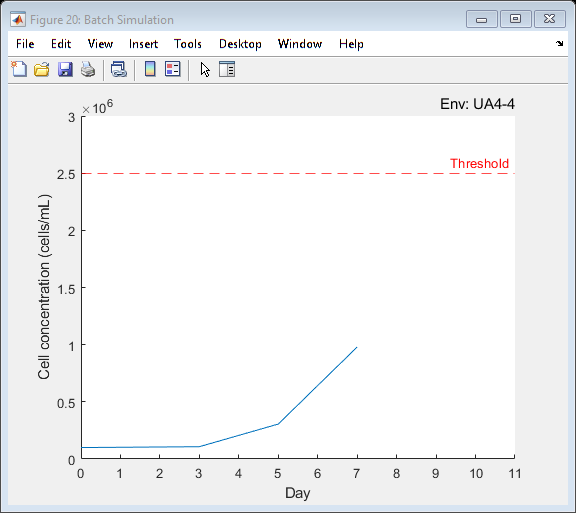

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA4-5"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


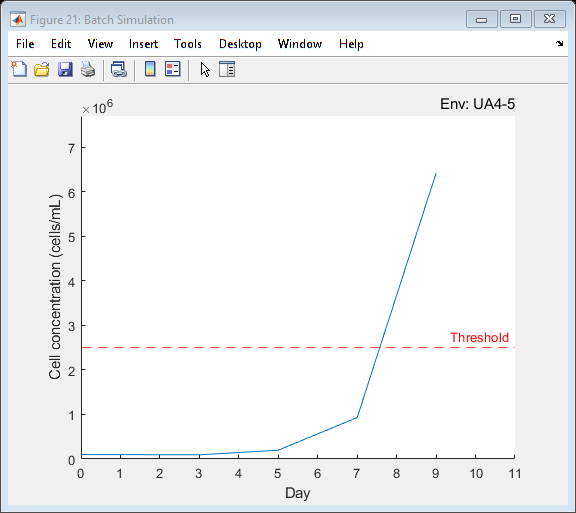

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA4-6"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


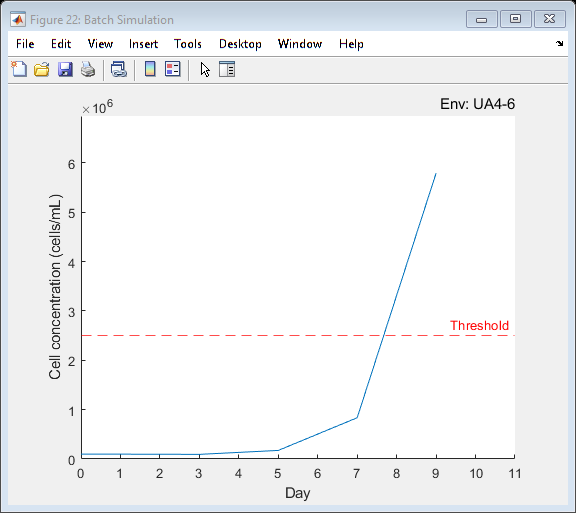

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA4-7"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


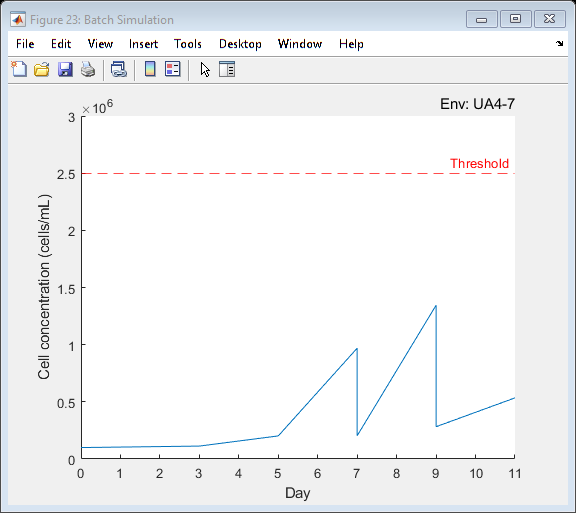

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA4-8"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [4×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


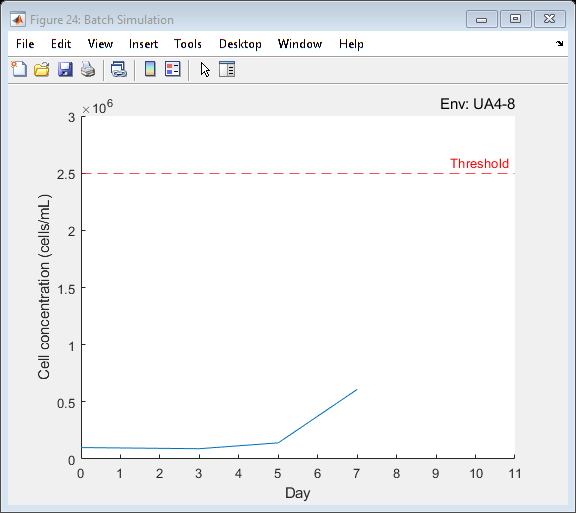

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA4-9"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [4×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


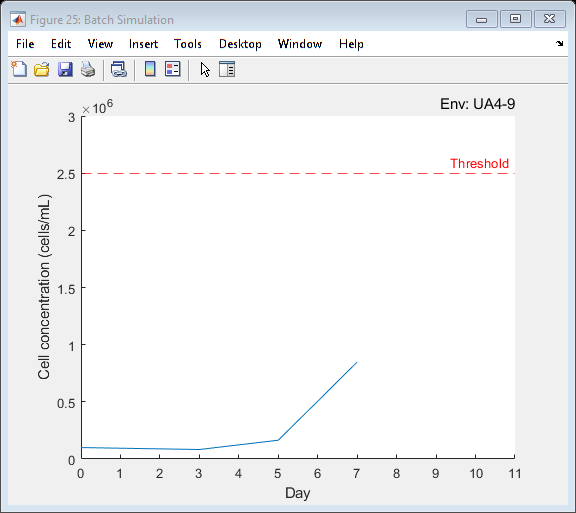

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA4-10"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [4×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


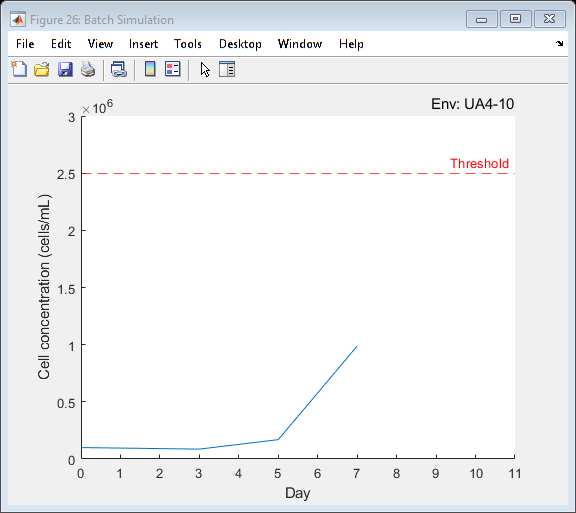

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA4-11"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [4×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


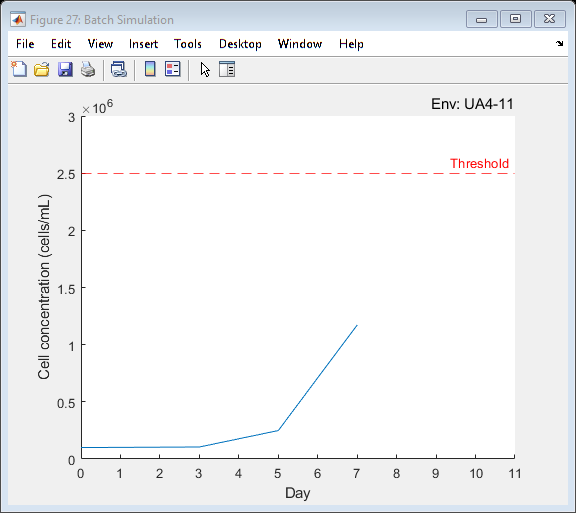

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA4-12"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [4×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


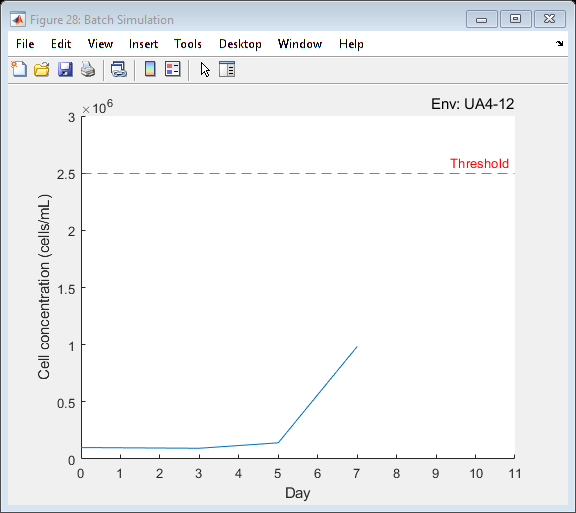

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA4-13"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


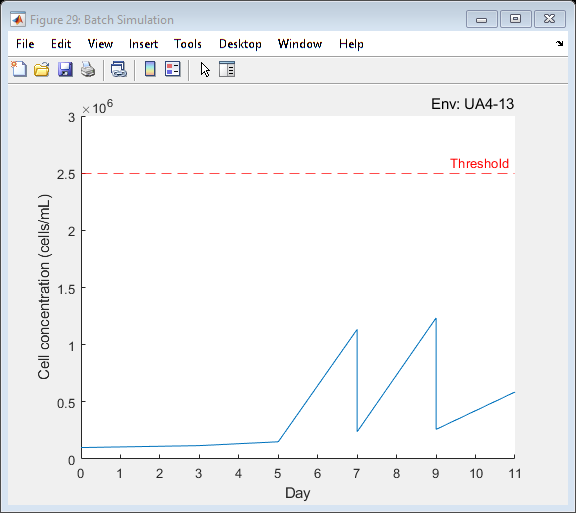

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA141-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [5×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


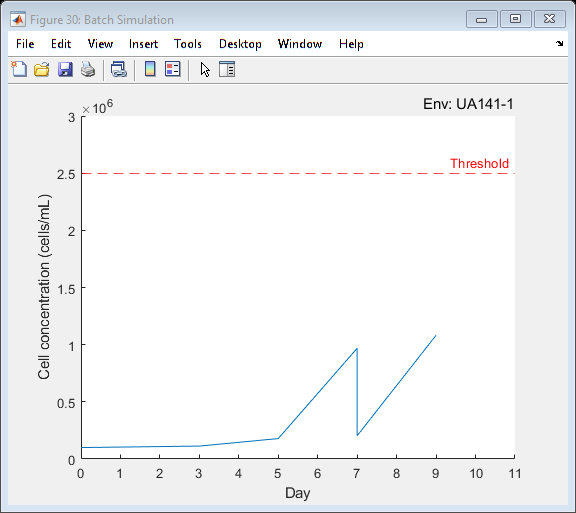

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA141-2"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


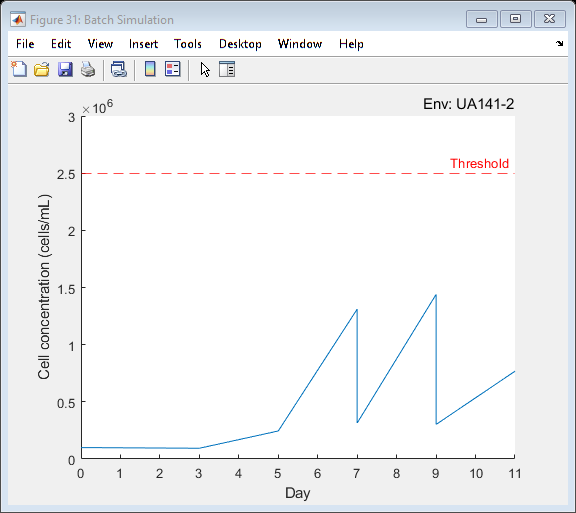

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA141-3"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


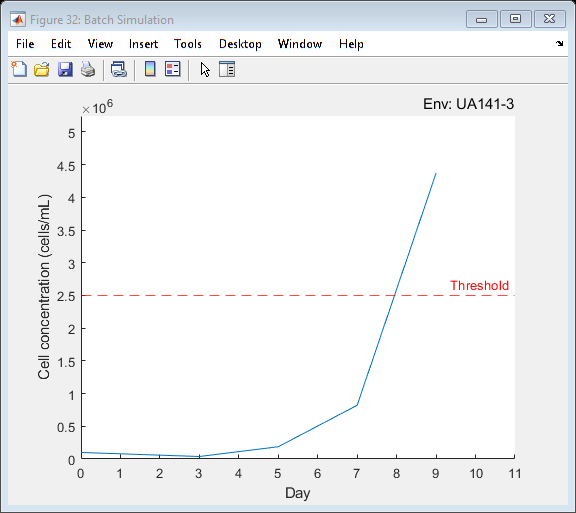

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA141-4"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [4×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


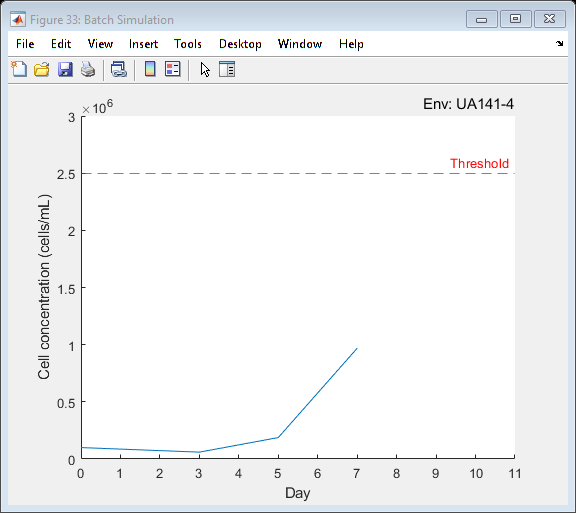

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA141-5"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


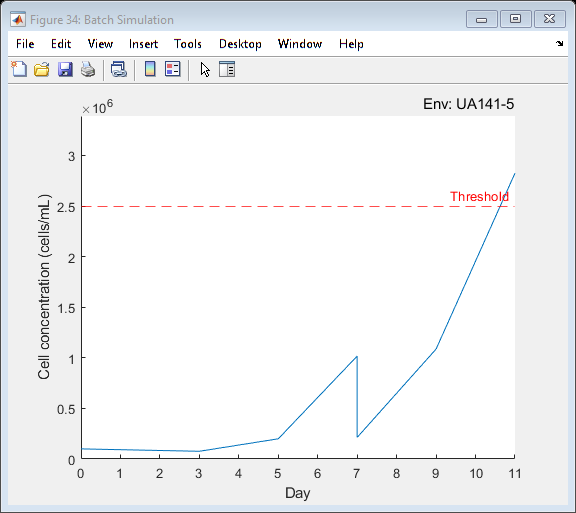

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA6-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [4×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


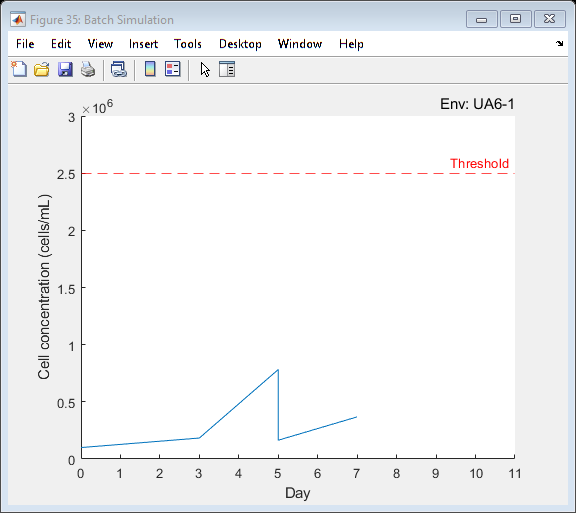

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA6-2"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [4×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


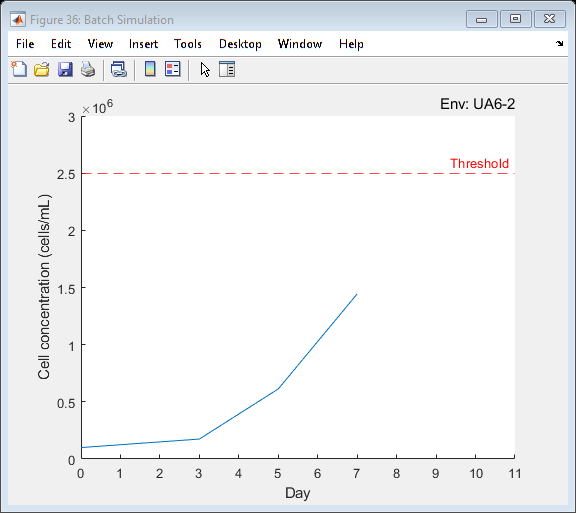

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA6-3"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [4×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


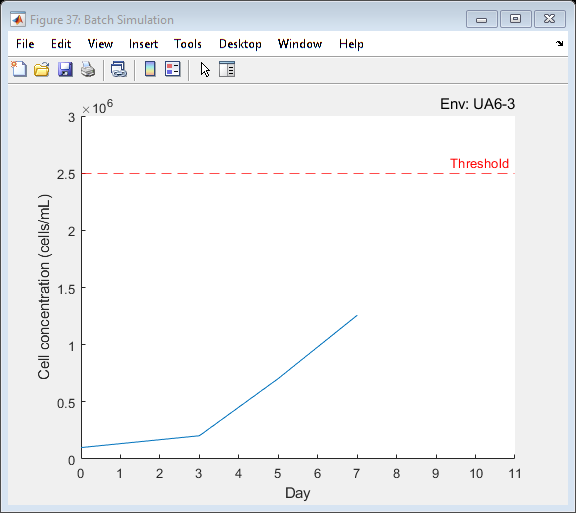

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA6-4"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [4×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


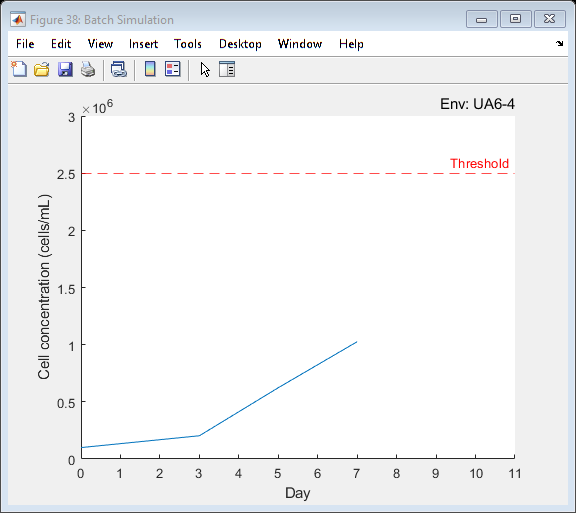

env3 =   modelEnv242 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "UA6-5"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×88 double]
                     numdonors: 8
                     foldExMap: [4×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


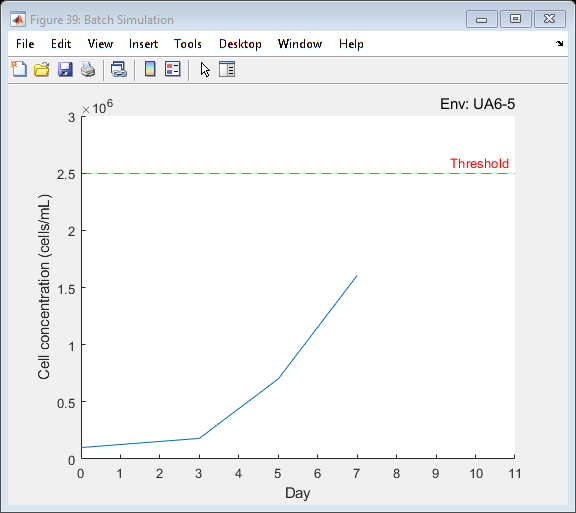

[simulationPlots,simulationResults] = simwithset(rawfoldincs,rawinitcons,rawdonornames,dqnagent);

[rewardMatrix,totalRewards,totalReward,averageReward] = calculatescore(6,simulationResults)

rewardMatrix =             0       0.1078        0.153       0.1358       0.1548       0.1052       0.1052        0.094       0.0718      0.10855        0.119       0.1131      0.15582       0.1952      0.11377      0.11583      0.10556       0.0962       0.1076        0.094        0.094        0.113         0.09        0.083       0.0865        0.105        0.094        0.117        0.113        0.094        0.038         0.06      0.07625       0.1834       0.1744       0.2032       0.2032       0.1804
            1         0.66      0.70622      0.58019      0.98152      0.58439      0.58439        0.576        0.436      0.45014      0.60241      0.52239      0.61515      0.94286      0.48429      0.41998      0.38507      0.35407      0.30578       0.1975      0.17375      0.20187      0.14125      0.16438      0.16937      0.24875       0.1415      0.15062      0.17875        0.245       0.1875       0.1875      0.19969      0.78275      0.61284      0.70388      0.62342      0.7

totalRewards =       -3.6878      0.68603       2.0376       1.0881       7.9027       15.002     -0.66227       2.2351      -0.9647      -3.8518       2.6568       13.567      -1.7407       2.5292       1.9444       1.2554       1.5953       1.3931      -14.437      -12.055      -1.8361      0.83984       1.0951       1.2439       1.5255       1.2194       -1.778     -0.15669      -1.1427      -6.4292       1.2163       1.0791      -1.1653       2.2311       2.1642       1.8528       2.4868


totalReward =         20.94


averageReward =       0.56595


function [trialfoldincs, trialinitcons, trialdonornames] = initializedatasets(seed,allmodelfoldincs,modelinitcons,rawfoldincs,rawinitcons,rawdonornames,donoridxmap,donorlist)
    rng(seed);
    trainingvector = sort(randperm(9,6),"ascend");
    trainingset = donorlist(trainingvector);
    
    trainingset = [trainingset ["UA4","UA141"]]
    
    validationvector = [];
    for i=1:12
        if ismember(i,trainingvector)==false
            validationvector = [validationvector i];
        end
    end
    validationvector = sort(validationvector,"ascend");
    validationset = donorlist(validationvector)
    
    availmodelfoldincs = [allmodelfoldincs(:,1:numel(modelinitcons)*9)];
    
    trialmodelfoldincs = [];
    for i=trainingvector
        trialmodelfoldincs = [trialmodelfoldincs availmodelfoldincs(:,(numel(modelinitcons)*(i-1)+1):(numel(modelinitcons)*(i-1)+numel(modelinitcons)))];
    end    
    
    trialmodelfoldincs = [trialmodelfoldincs allmodelfoldincs(:,(numel(modelinitcons)*9+1):(numel(modelinitcons)*11))]
    
    writematrix(trialmodelfoldincs, "modelfoldincs.txt")
    
    trialfoldincs = [];
    trialinitcons = [];
    trialdonornames = [];
    for i=validationvector
        trialfoldincs = [trialfoldincs rawfoldincs(:,donoridxmap{i})];
        trialinitcons = [trialinitcons rawinitcons(donoridxmap{i})];
        % POTENTIALLY BETTER IF ALL NORMALIZED TO 500000
        trialdonornames = [trialdonornames rawdonornames(donoridxmap{i})];
    end
end 

function dqnagent = dqninittraining(seed,numdonors)
    rng(0);    
    % create first environment
    env = modelEnv242;
    env.useCustom = false;
    env.numdonors = numdonors;
    obs = getObservationInfo(env);
    acts = getActionInfo(env);
    validateEnvironment(env)
    
    % hyperparameters
    discountFactor = 1;
    epsilon = 1;
    epsilondecay = 0.00125;
    
    initOpts = rlAgentInitializationOptions;
    initOpts.NumHiddenUnit = 64;
    initOpts.UseRNN = false;
    
    dqnagentoptions = rlDQNAgentOptions;
    dqnagentoptions.DiscountFactor = discountFactor;
    dqnagentoptions.EpsilonGreedyExploration.Epsilon = epsilon;
    dqnagentoptions.EpsilonGreedyExploration.EpsilonDecay = epsilondecay;
    dqnagentoptions.SequenceLength = 1;
    dqnagentoptions.UseDoubleDQN = false;
    
    dqnagent = rlDQNAgent(obs,acts,initOpts,dqnagentoptions);
    % plot(layerGraph(getModel(getCritic(dqnagent)).Layers));
    
    trainopts = rlTrainingOptions;
    trainopts.MaxEpisodes = 1500;
    trainopts.StopTrainingCriteria = "EpisodeCount";
    trainopts.StopTrainingValue = 1500;
%     trainopts.StopTrainingCriteria = "AverageReward";
%     trainopts.StopTrainingValue = 13.5;
    %trainopts.Plots = 'none';
    %trainopts.Verbose = true;
    
    plot(env)
    results = train(dqnagent,env,trainopts);
end

function [plots,experiences] = simwithset(foldExMaps,day3cons,donornames,sarsaagent3)
    plots = cell(size(foldExMaps,2),1);
    experiences = cell(size(foldExMaps,2),1);
    for i=1:size(foldExMaps,2)
        %creating foldexmap
        foldExMap1 = foldExMaps(:,i);
        foldExMap1 = foldExMap1(~isnan(foldExMap1));
        idx = foldExMap1==1;
        idx(1) = false;
        foldExMap1(idx) = [];
        
        %creating new env
        env3 = modelEnv242;
        env3.useCustom = true;
        env3.foldExMap = foldExMap1;
        %NORMALIZED INIT CONS
        %
        env3.initialState = [100000/1000000,1];
        env3.modelInfo = donornames(i)
        validateEnvironment(env3)
        
        % plot now
        plot(env3);
        experiences{i} = sim(sarsaagent3,env3);
        plots{i} = env3.Figure;
    end
end

function [rewardMatrix,totalRewards,totalReward,averageReward] = calculatescore(maxSeriesLength,simulationResults)
    maxSeriesLength = 5;
    rewardMatrix = [0:(maxSeriesLength-1)]';
    for i=1:size(simulationResults,1)
        seriesRewards = simulationResults{i}.Reward.Data;
        if size(seriesRewards,1)<maxSeriesLength
            numZeros = maxSeriesLength - size(seriesRewards,1);
            for j=1:numZeros
                seriesRewards = [seriesRewards; 0];
            end
        end
        rewardMatrix = [rewardMatrix seriesRewards];
    end
    totalRewards = [];
    for i=2:size(rewardMatrix,2)
        totalRewards = [totalRewards sum(rewardMatrix(:,i))];
    end
    totalReward = sum(totalRewards);
    averageReward = mean(totalRewards);
end